# Plate Reader 2 -- experiment 1

## Step 1: data loading and preparation

Add PLATERO set of functions to your working directory:

my = version('-release');
if str2double(my(1:4))<2020
addpath(genpath('rprev2020'))
else
addpath(genpath('r2020'))
end

Now, load the data resulting from the calibration experiment, written in "`filename`". This data is organized by sheets, where each sheet has one repetition of the measurements.

filename = "PlateReader2_exp1.xlsx";
colnames = {'WellID','Well','Concentration','G50','G60','G70','G80','G90','G120'};
[dataPR, indgfp] = readexperiment(filename,"A7:I103",[50:10:90,120],false,colnames,0);
size(dataPR)

ans =         4608           5


Divide the dataset into the subset with medium values (`dataPRblk`) and the set with fluorescein values (`dataPRgfp`).

datPRblk = dataPR(~indgfp,:);
datPRgfp = dataPR(indgfp,:);
disp(strcat("This data set has ", string(size(datPRblk,1)),...
" BLK observations and ", string(size(datPRgfp,1)), ...
" GFP observations."))

This data set has 768 BLK observations and 3840 GFP observations.


Obtain the partition of the fluorescein dataset into the model building set  (70%) and the model validation set (30%). A seed is set to ensure reproducibility of the results. The resulting subsets are stored as the `calibration_PR1.mat `and the `validation_PR1.mat `files.

rng(0207)
[datagfp_cal, datagfp_val] = cvsplit(datPRgfp, 0.7);
disp(strcat("The calibration data set has ", string(size(datagfp_cal,1)),...
" observations and the validation data set has ", ...
string(size(datagfp_val,1)), " observations."))

The calibration data set has 2640 observations and the validation data set has 1200 observations.


data_cal_pr2 = [datPRblk; datagfp_cal];
save('calibration_PR2.mat',"data_cal_pr2")
save('validation_PR2.mat',"datagfp_val")

## Step 2: Model Building step

Load the calibration subset, fit the model and store the coefficients.

Explorative plot of missing data for each concentration level: 


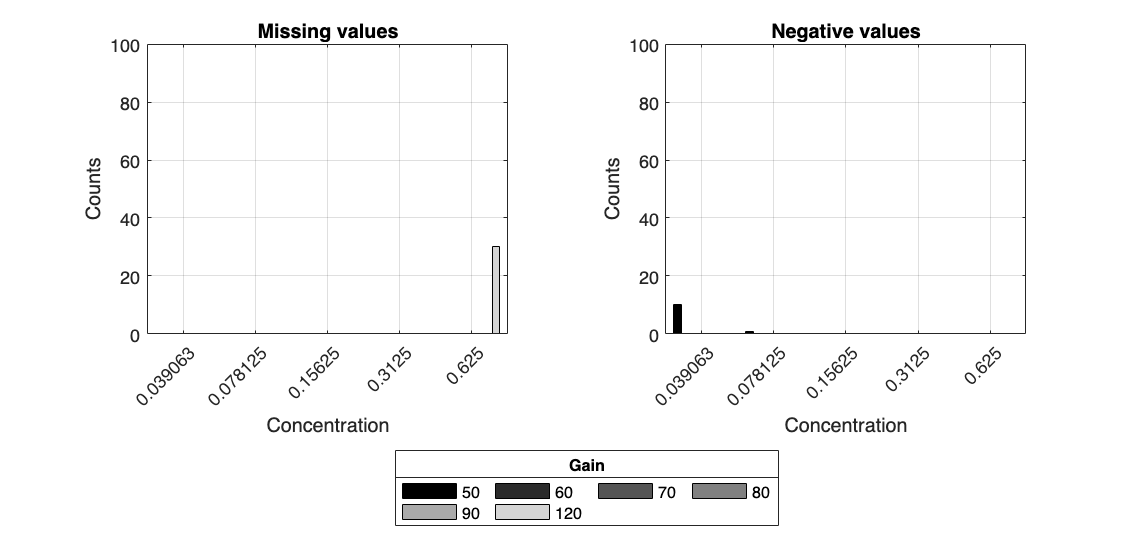

Concentration(s)0.625 had missing values
Concentration(s)0.0391, 0.0781 had negative values
Gain(s)120 had missing values
Gain(s)50 had negative values
Explorative plot of the raw F_observed Fluorescein data: 


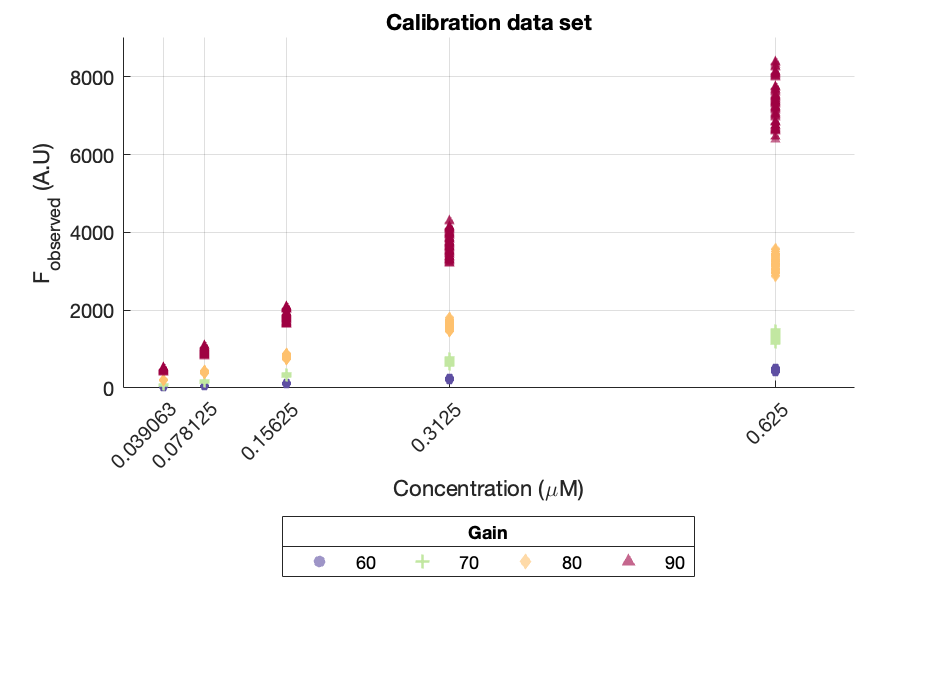

Explorative plot of the raw F_BLK data: 


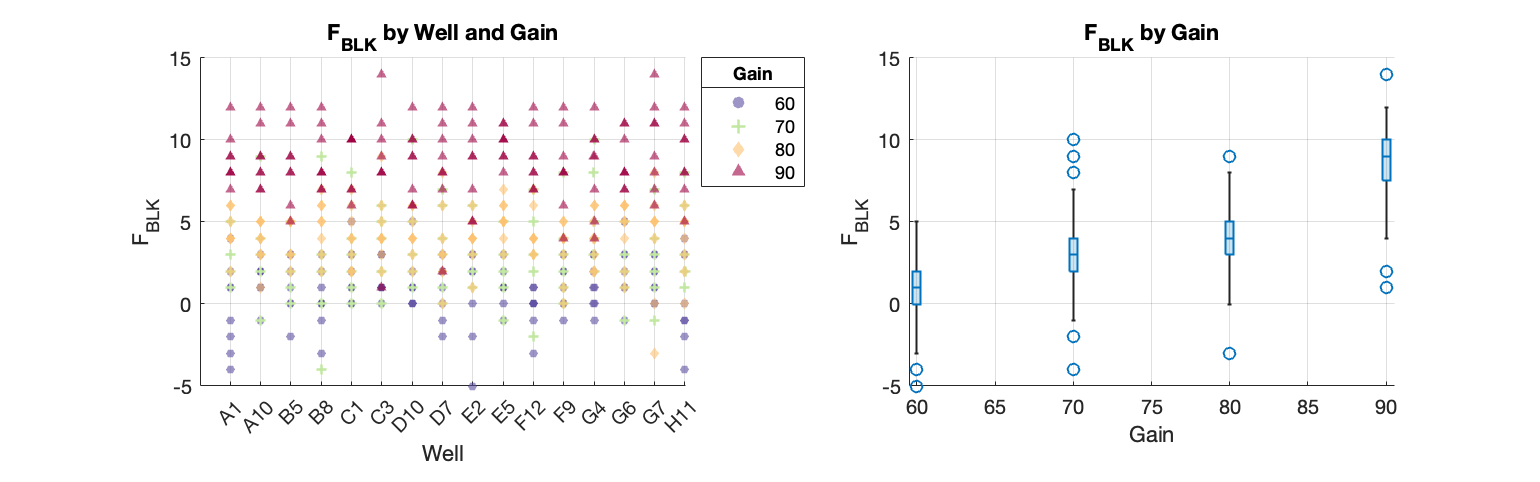

data_cal_pr2 = load("calibration_PR2.mat").data_cal_pr2;
[blk_data, flu_data_PR2e1] = explore_data(data_cal_pr2, 0);

Fit f_G and plot corrected data (F_reporter): 
ANOVA on coefficient b_1 for all levels of concentration


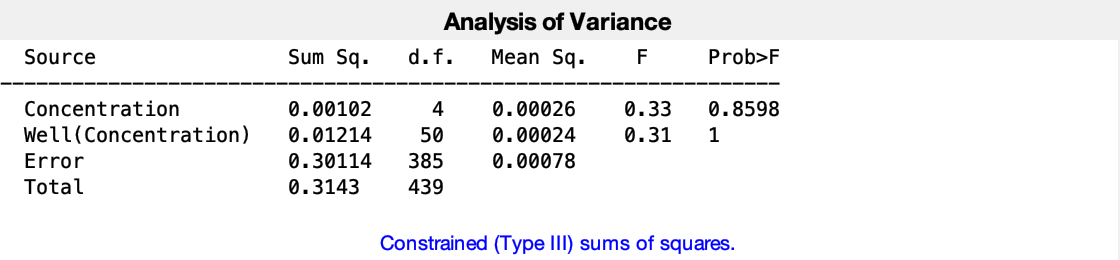

ANOVA on coefficient b_2 for all levels of concentration


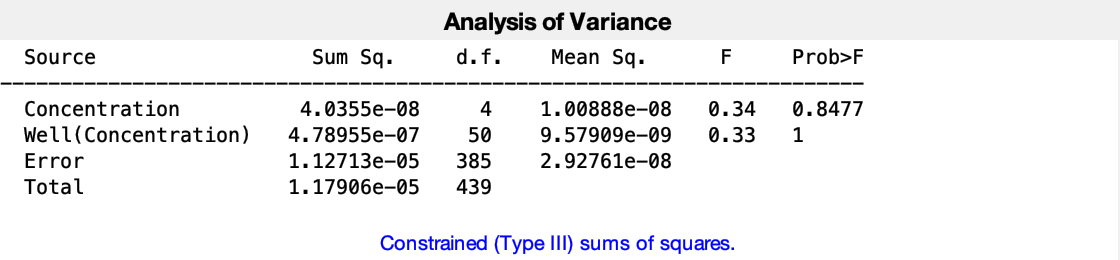

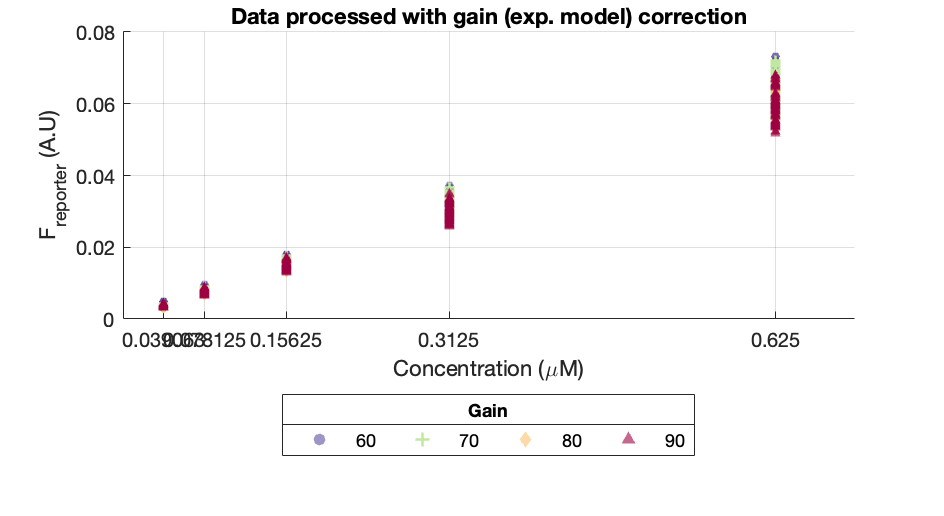

Fit f_UC and plot estimated concentration data (C): 


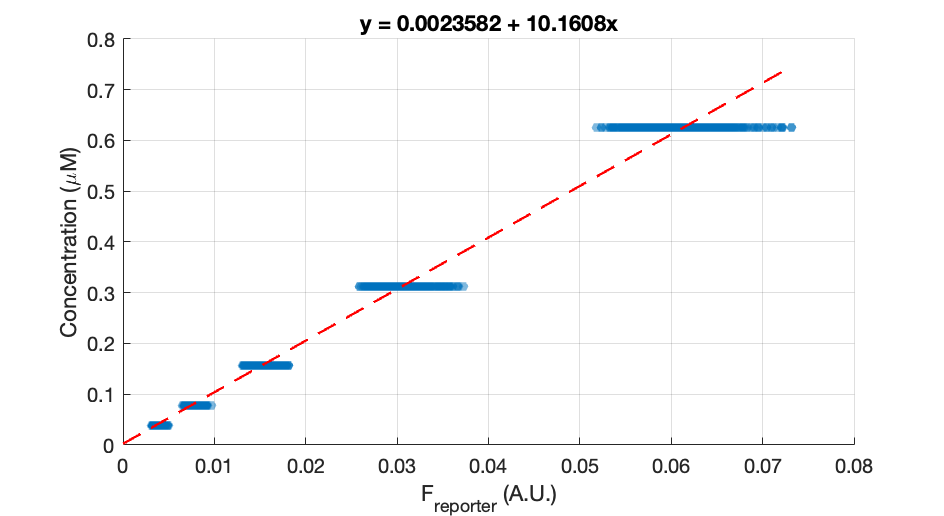

Analize the bias in the predictions and estimate the uncertainty in the predictions (s_Bias): 


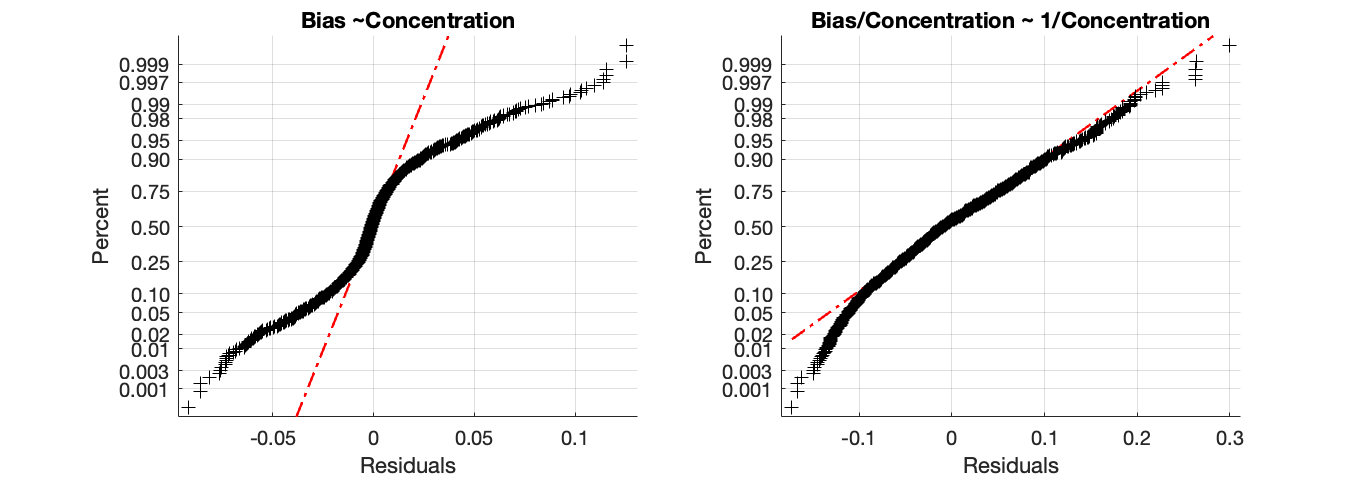

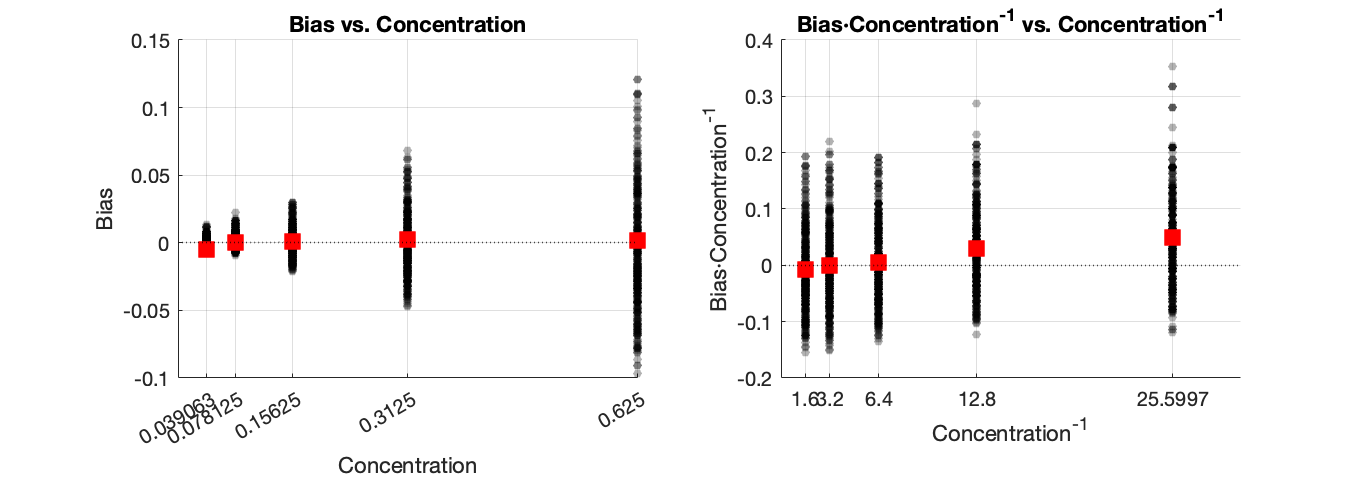

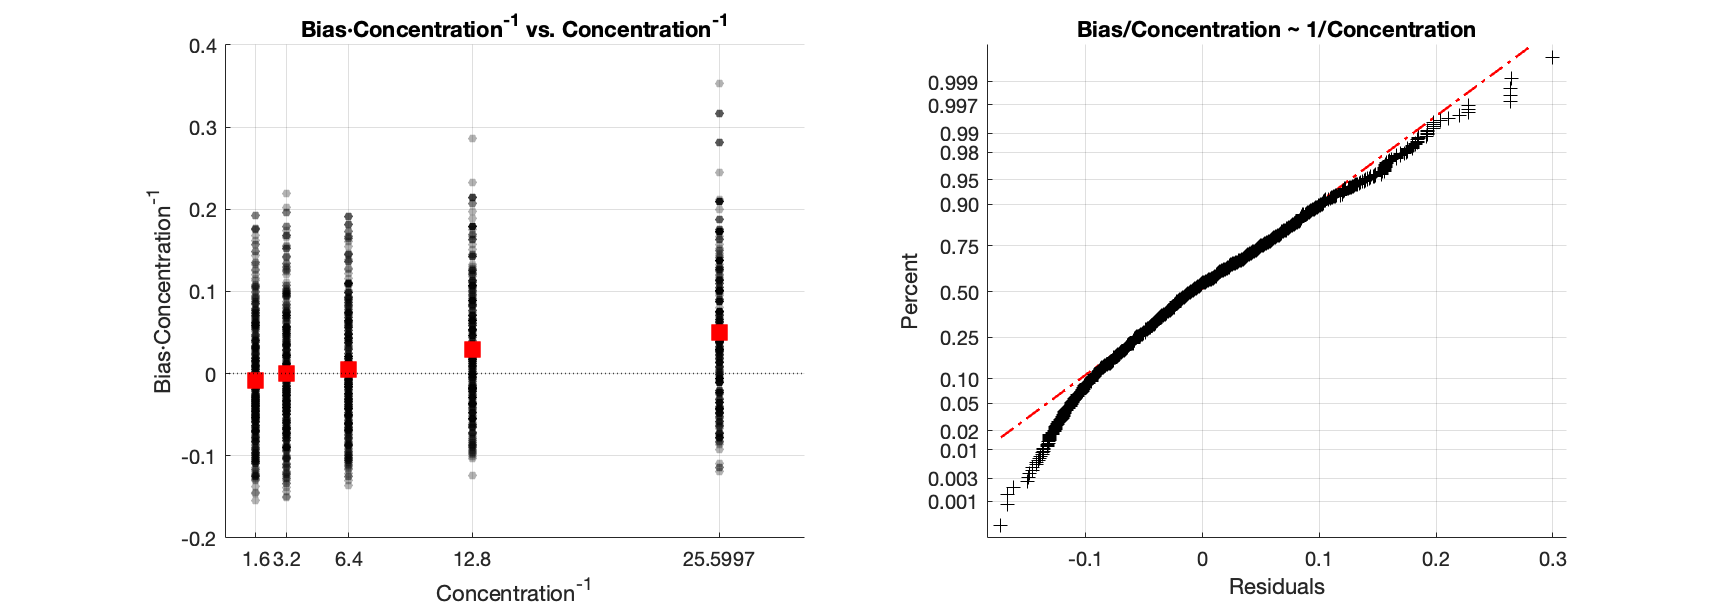

Compute error metrics for the Model Building step: 
    F_BLK (G = 60)    F_BLK (G = 70)    F_BLK (G = 80)    F_BLK (G = 90)      b1           b2            c0          c1       sBias      EDF 
    ______________    ______________    ______________    ______________    _______    ___________    _________    ______    ________    ____

          1                 3                 4                 9           0.18389    -0.00059598    0.0023582    10.161    0.078957    1758



[flu_data_PR2e1, modelPR2e1, calmetrics_PR2e1] = fit_platero_model(blk_data, flu_data_PR2e1,...
    "PR_2e1");

## Step 3: Model Validation step

A 0 % of the observations was missing.
Plot the Validation dataset transformed to concentration units: 


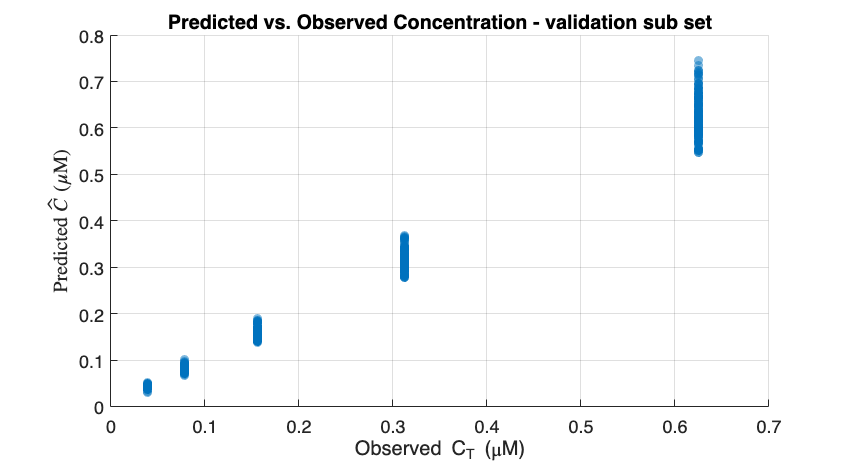

R&R Analysis: 
R & R Analysis on measurements for C = 0.039063


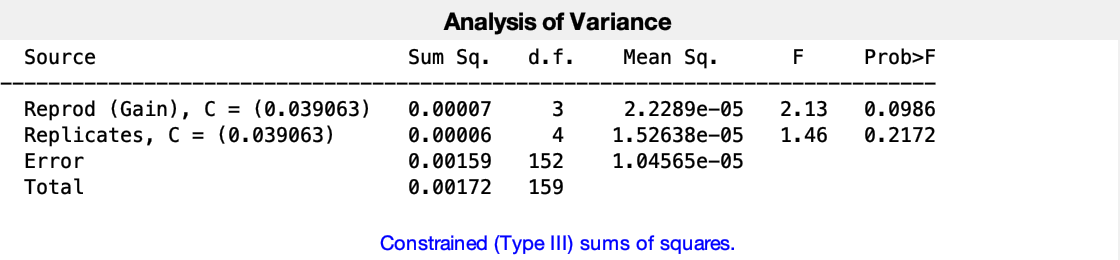

R & R Analysis on measurements for C = 0.078125


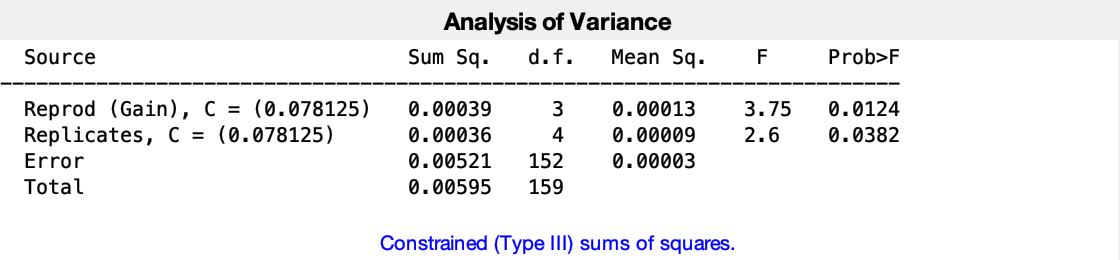

R & R Analysis on measurements for C = 0.15625


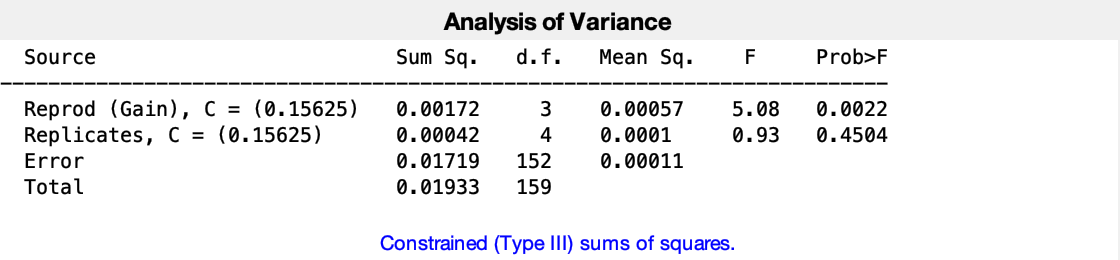

R & R Analysis on measurements for C = 0.3125


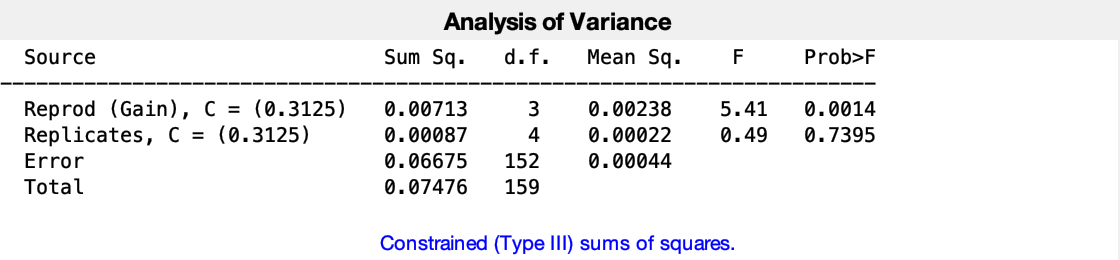

R & R Analysis on measurements for C = 0.625


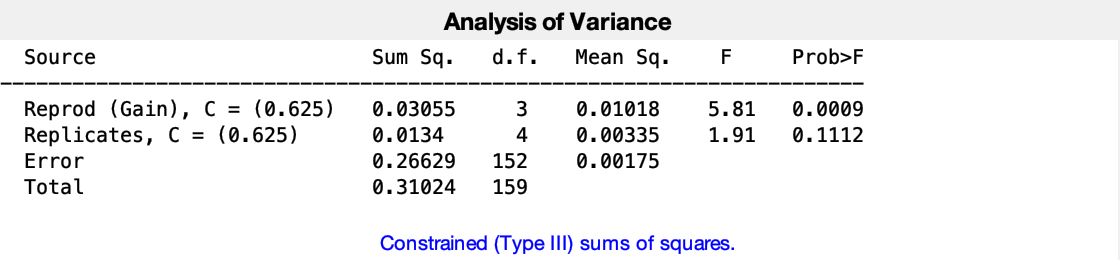

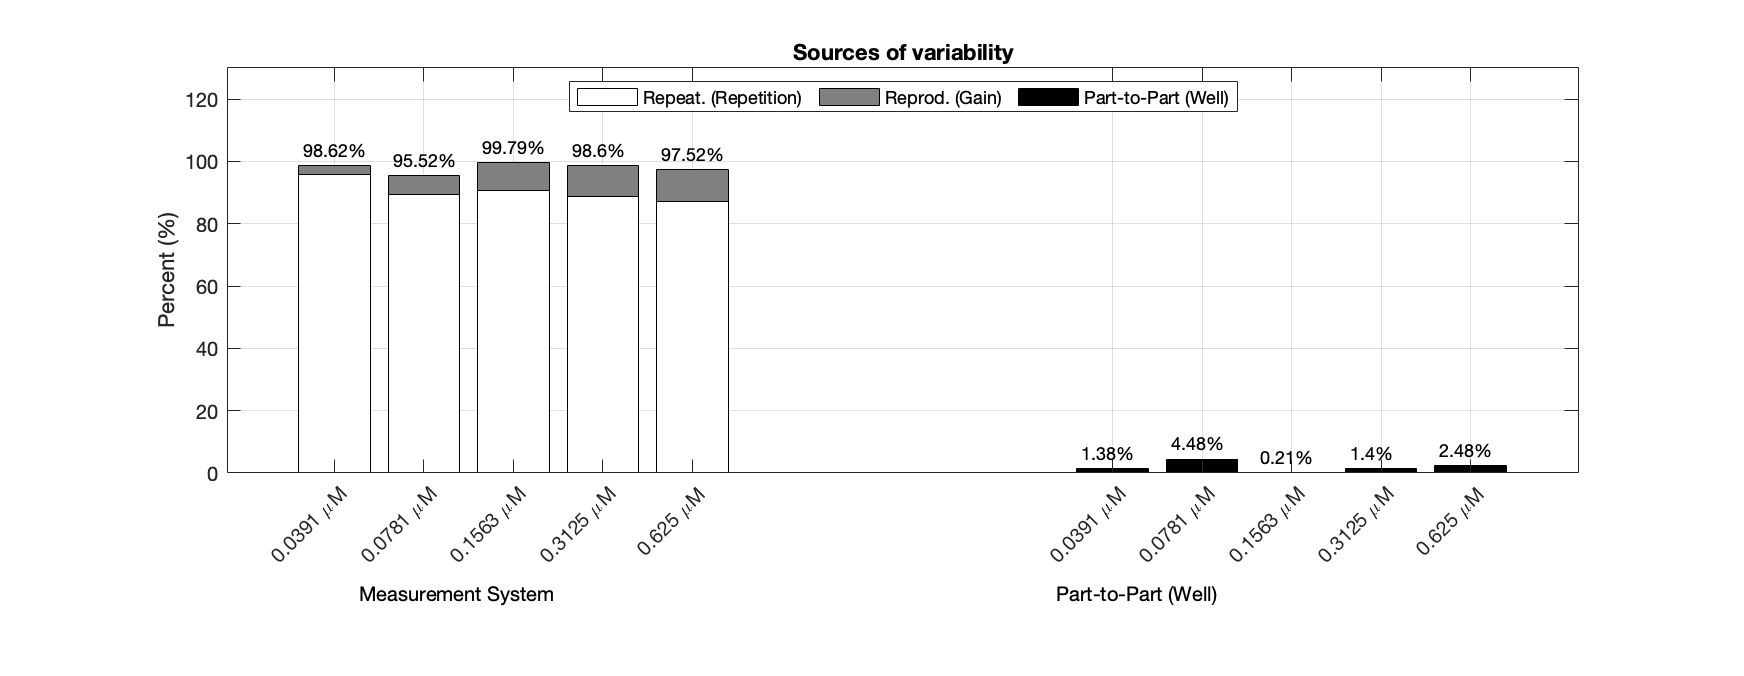

 
B&L Analysis: 


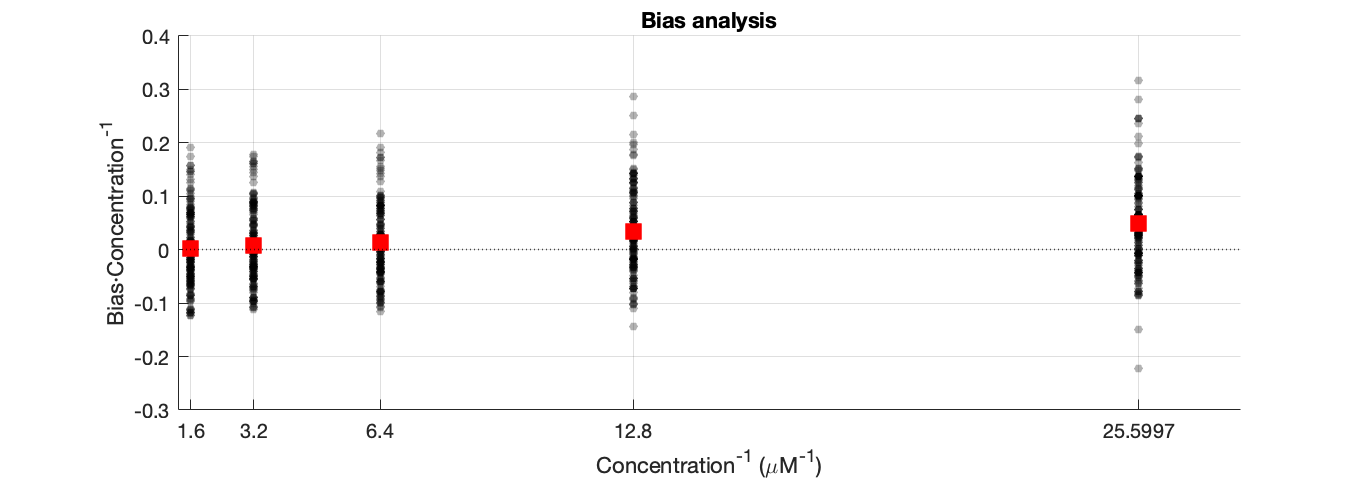

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue  
                   _________    __________    ______    __________

    (Intercept)    0.0019598     0.0040028    0.4896       0.62455
    x1             0.0019459    0.00030294    6.4233    2.2893e-10


Number of observations: 800, Error degrees of freedom: 798
Root Mean Squared Error: 0.0748
R-squared: 0.0492,  Adjusted R-Squared: 0.048
F-statistic vs. constant model: 41.3, p-value = 2.29e-10
-------------------------------------------------------------------
Contribution of model terms to the total bias variability:
Bias Model - linear term (%): 0.196 %
Bias Model - bias term (%): 4.4521 %
 
Confidence Intervals and Error metrics: 
        pctgeci: 97.5000
            mse: 5.1973e-04
  

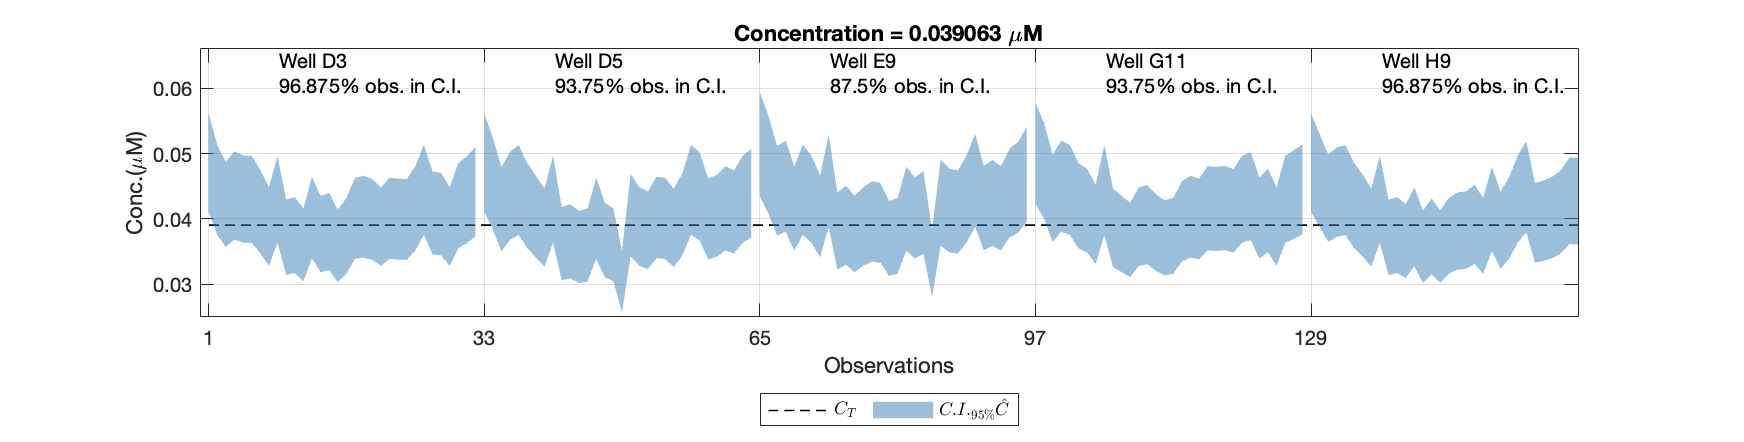

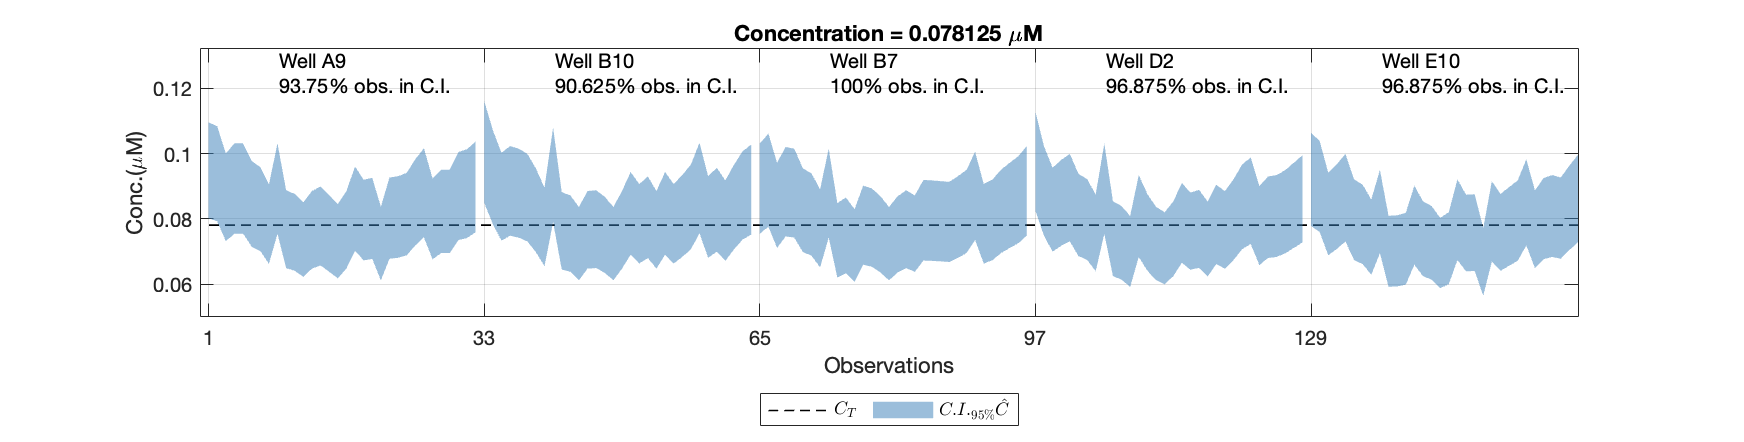

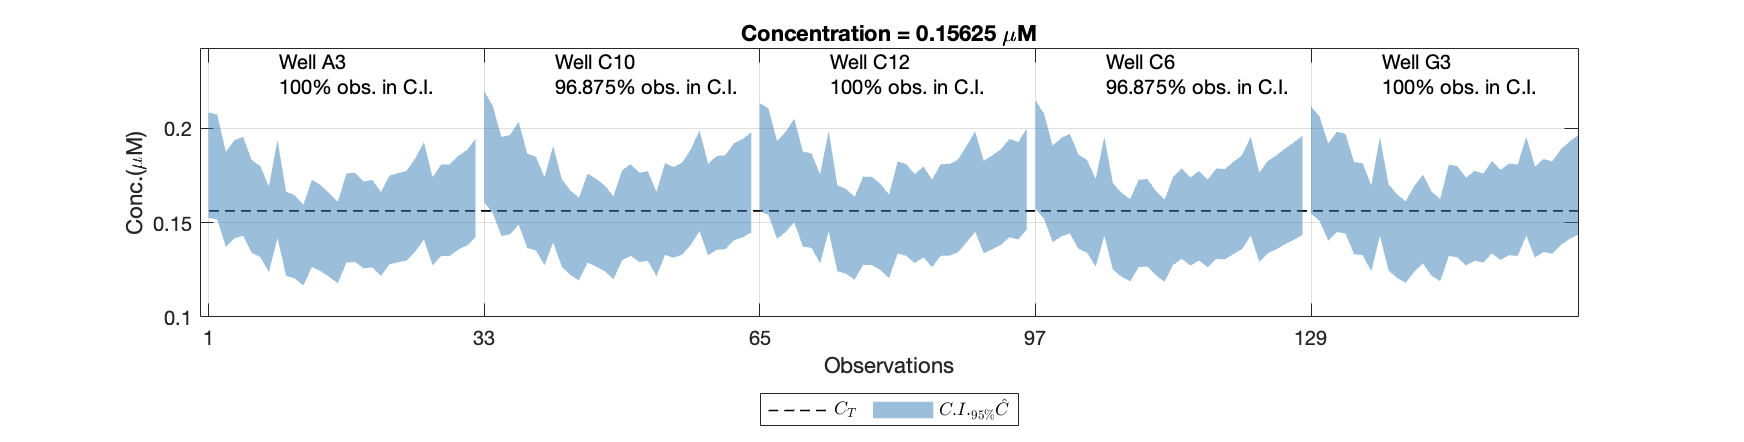

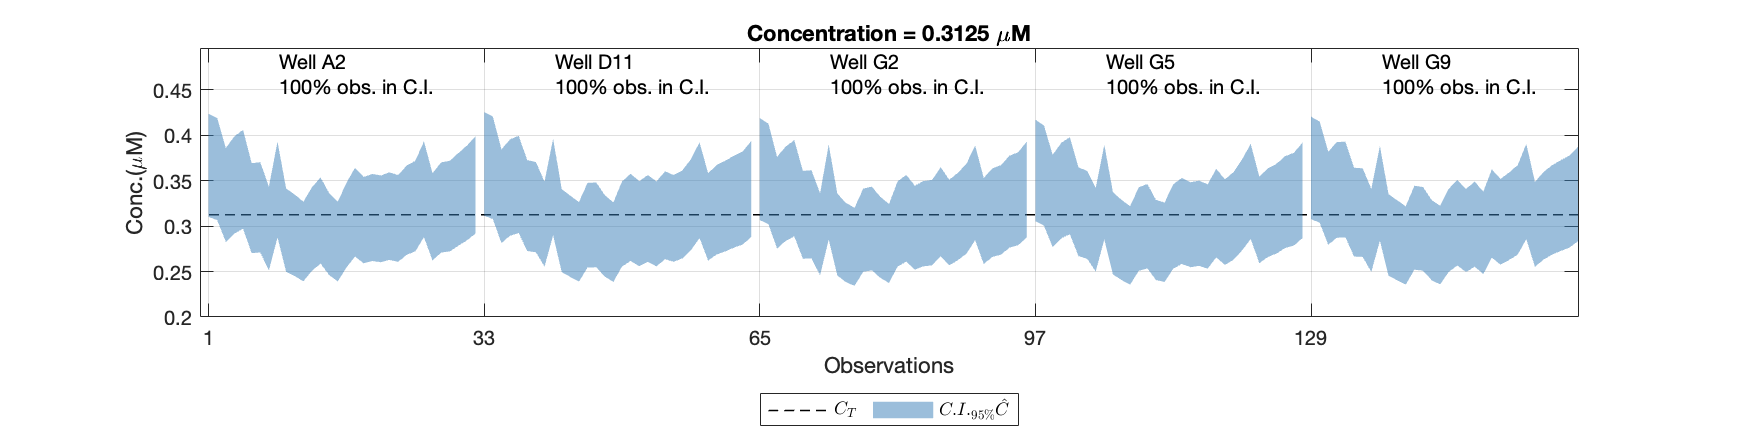

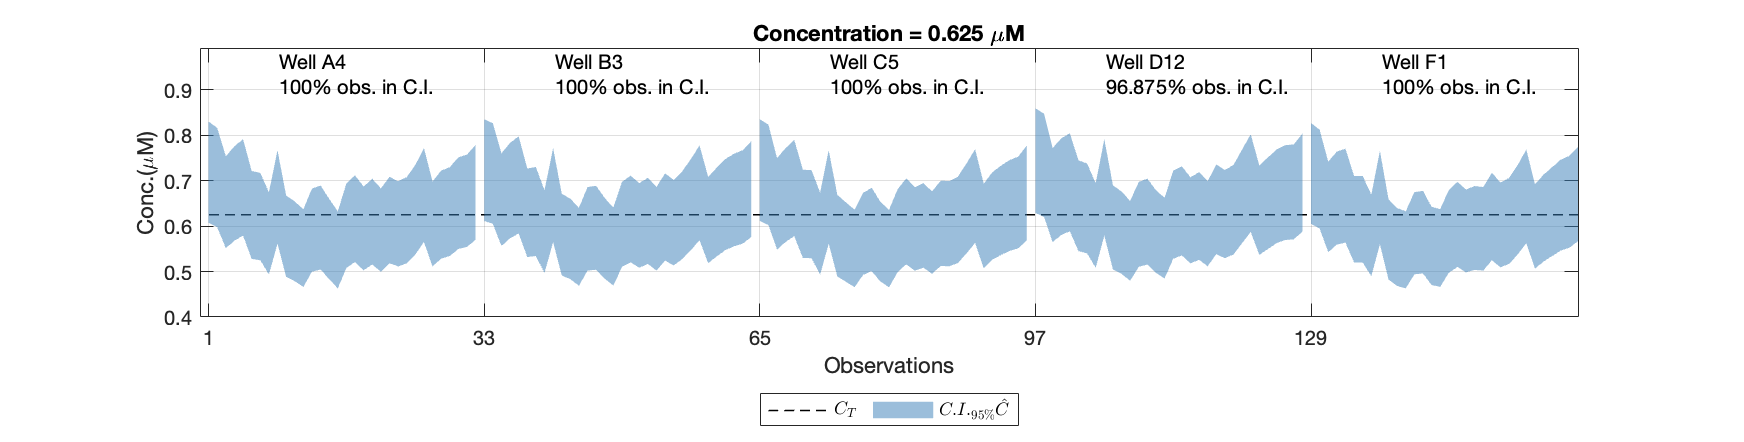

datagfp_val = load("validation_PR2.mat").datagfp_val;
uG = unique(flu_data_PR2e1.Gain);
uC = unique(flu_data_PR2e1.Concentration);
data_val_pr2e1 = datagfp_val(ismember(datagfp_val.Gain, uG),:);
G = unique(data_val_pr2e1.Gain);

% Assign the correspoding F_BLK values to each observation F_obs
data_val_pr2e1.Fblk = repmat(modelPR2e1{:,1:4}', size(data_val_pr2e1,1)/length(G),1);

% Run the model on the validation set
[data_val_pr2e1, valmetrics_inrange, vprocv] = use_platero_model(data_val_pr2e1, ...
    modelPR2e1,"PR_2e1");


% Comparison between calibration-set and validation-set metrics
% load(strcat(dirdatasave,'cal_results.mat'))
perftable = table([calmetrics_PR2e1.mse;valmetrics_inrange.mse],...
[calmetrics_PR2e1.minrelerror;valmetrics_inrange.minrelerror]*100,...
[calmetrics_PR2e1.maxrelerror;valmetrics_inrange.maxrelerror]*100,...
'RowNames',{'Calibration', 'Validation (within range)'},...
'VariableNames',{'MSE','Min.Rel.Error (%)','Max.Rel.Error (%)'});
display(perftable)

perftable = 2×3 table
                                    MSE        Min.Rel.Error (%)    Max.Rel.Error (%)
                                 __________    _________________    _________________

    Calibration                  0.00055309        0.0045475             35.277      
    Validation (within range)    0.00051973       0.00083939             31.687      
